## **CU Anshutz-Medtronic Percieve Collaboration**

The purpose of this report is to illustarte key findings from the data acquisition and early analysis portion of this study. 

This section loads in variables that are useful to the other fuctions. Further, this section helps to process files coming from a patient with either single or double batteries, enhancing the modularity of the code. 

clear
cd('C:\Users\sydne\Documents\github\perceive')
jsonFiles = 'Report_Json_Session_Report_Patient1_right_init.json';
%For this particular patient, this file encodes the RIGHT side 
js = jsondecode(fileread(jsonFiles));
cd('C:\Users\sydne\Documents\github\perceive') 

channels = unique({js.LfpMontageTimeDomain.Channel}, 'stable');
leng = numel({js.LfpMontageTimeDomain.Channel});
startindex = 7; %bc the first trial was not good, we skip all 6 channels
sides = {'LEFT', 'RIGHT'};
if any((contains(channels, sides{1}))) && any((contains(channels, sides{2}))) 
        doubleBattery = false; 
        %json has both left and right data 
        channelsLeft = channels(contains(channels, sides{1}));
        channelsRight = channels(contains(channels, sides{2}));
    else 
        doubleBattery = true; 
end 


#### Frequency vs power plot for all contact pairs

After data is collected from Brainsense, the three trials are averaged and presented as a single line. All six pairs are represented. Smoothing has maintained the shape of the curve but altered the power, thus not always matching the maximum power reported. 

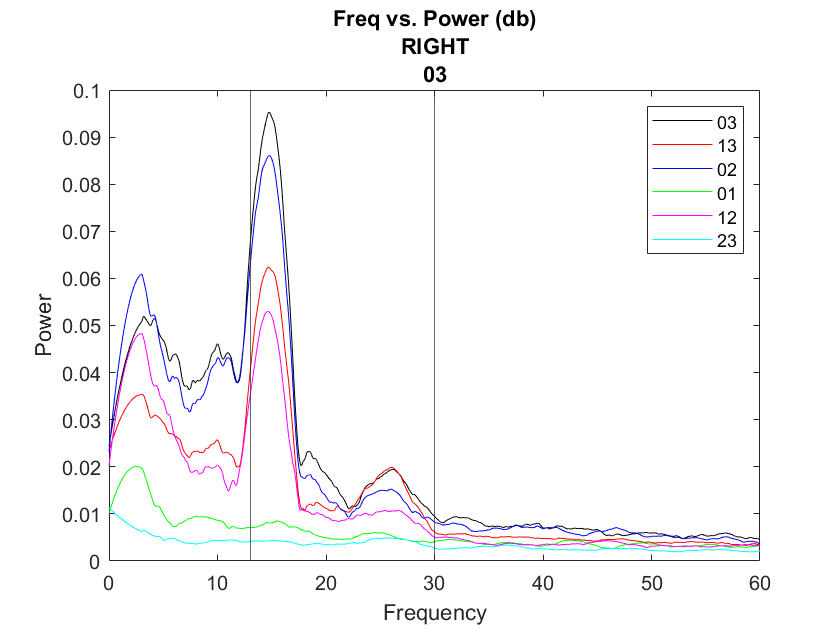

 colors = 'krbgmc';
    maxValues = zeros(length(channels), 1);
    for c=1:length(channels)
        maxValues(c) = tempAvgPlot(7, leng, js, channels{c}, colors(c));
        hold on;
    end 
    
    [M, I] = max(maxValues);
    highestBeta = channels{I};
    
    %add all the plot info
    
    xline(13);
    xline(30);
    
   legendChan = cell(6);
        oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'}; 
        newchar = {''}; 
        oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'}; 
        newnum = {'0', '1', '2', '3'};
        for b = 1:length(channels)
            legendChan{b} = replace(channels{b}, oldchar, newchar);
            legendChan{b} = replace(legendChan{b}, oldnum, newnum);
        end
        legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6}) 
        
    title(["Freq vs. Power (db)", "RIGHT", legendChan{I}])
    xlim([0 60])
    xlabel("Frequency")
    ylabel("Power")

disp(['The highest beta comes from contact pair', legendChan{I}])

The highest beta comes from contact pair03


#### Compare beta between contacts with standard deviation 

The average between all three trials is taken. Then, the max is found within the beta region and plotted. Standard devation is of the average of the three trails and within the beta region. 

    disp("Beta bar chart summary for the LEFT")

Beta bar chart summary for the LEFT


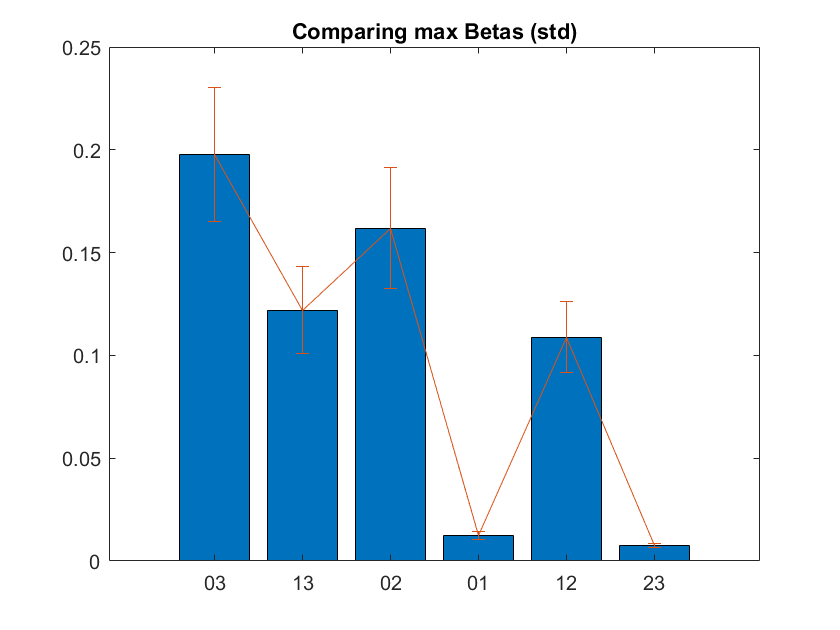

    compareBetaBarChart(startindex, leng, js, channels);

    figure;

#### All frequency spectrum for max beta contacts

For the contact pair that is determined to produce the most beta, full spectrum analysis was performed. Delta is defined as between 0-4.99Hz, theta is between 5-8.99Hz, alpha is 9-11.99Hz, beta is 12-33.99Hz, and gamma is from 34-100Hz. 

disp("All frequency bar chart summary for the LEFT")

All frequency bar chart summary for the LEFT


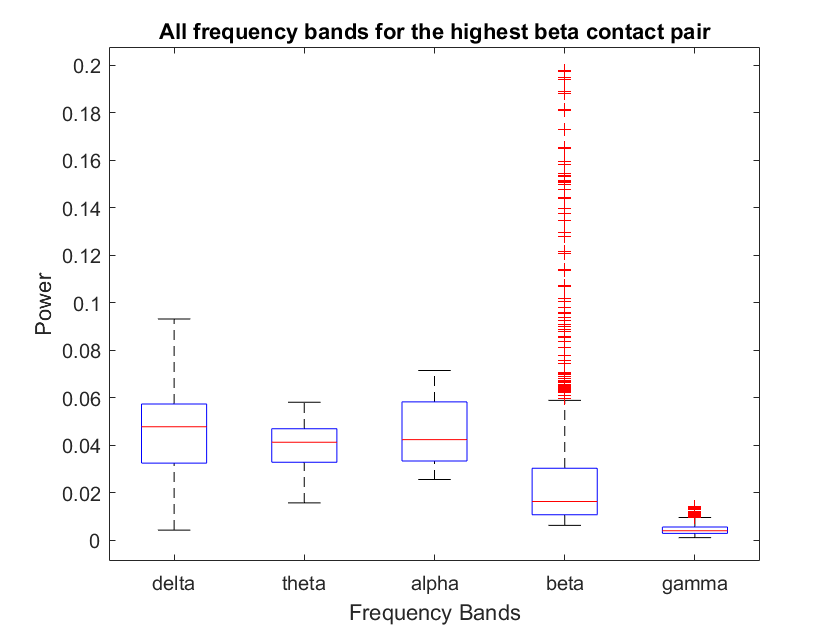

allFreqBarChart(startindex, leng, js, highestBeta)

#### Mean and Standard Deviation for each Trial

In descending order of beta activity, the means and stds of each contact pair is displayed. Each contact pair has the mean and std for each trial listed. These values come only from the beta region. A more concise visualization is below. Data is for the left and right. 

   %% 
   disp("Table trial summary for the LEFT")

Table trial summary for the LEFT


   maxMeanBetaAllRuns(startindex, js, leng, channels);

ans = 6×7 table
              Var1               Mean R1      Mean R2      Mean R3      STD R1       STD R2       STD R3  
    ________________________    _________    _________    _________    _________    _________    _________

    {'ZERO_THREE_LEFT_0'   }     0.031425     0.037135     0.026853     0.037616     0.052001     0.029113
    {'ZERO_TWO_LEFT_2'     }     0.029742     0.030355     0.022166     0.037525     0.042173     0.025512
    {'ONE_AND_TWO_LEFT_1'  }     0.022635     0.014758     0.015822      0.02779     0.013349     0.018358
    {'ONE_THREE_LEFT_1'    }     0.021793     0.026648     0.019482      0.02636     0.033415     0.017356
    {'ZERO_AND_ONE_LEFT_0' }    0.0063668    0.0055503    0.0055617    0.0036279    0.0022055    0.0025

#### Visualization of Trial Variability

For each contact, all three trials are plotted together to illustrate the variability from run-to-run for each Brainsense survey. Data has undergone smoothing that maintains the shape but not nessicarily the values. More granular information is in the table above. 

   disp("Graph trial summary for the LEFT")

Graph trial summary for the LEFT


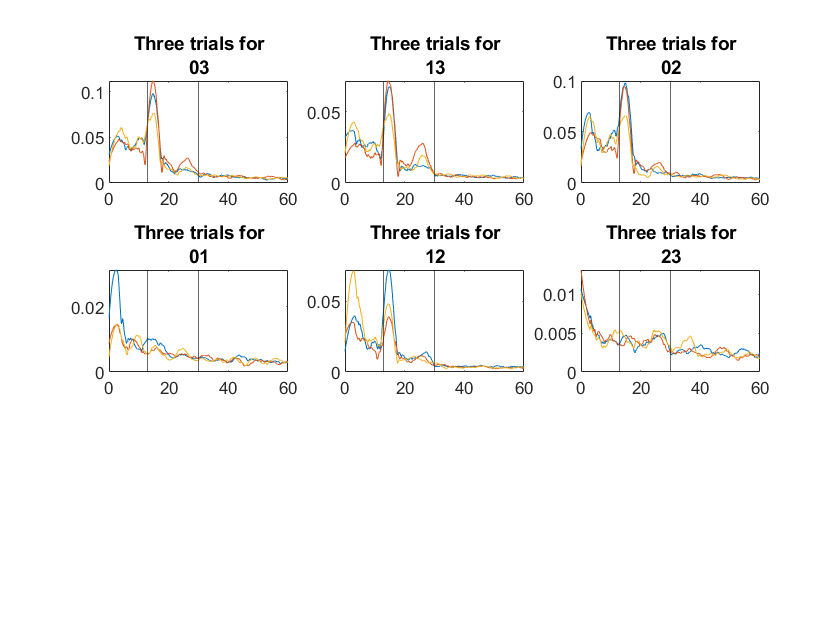

   graphEachTrials(startindex, js, leng, channels);

Info for the other side 

%%

cd('C:\Users\sydne\Documents\MATLAB\ThompsonLab\Patient1_0524')

Error using cd
Unable to change current folder to 'C:\Users\sydne\Documents\MATLAB\ThompsonLab\Patient1_0524' (Name is nonexistent or not a folder).

jsonFiles = 'Report_Json_Session_Report_20210524T101039.json';
js = jsondecode(fileread(jsonFiles));
cd('C:\Users\sydne\Documents\MATLAB\ThompsonLab')

channels = unique({js.LfpMontageTimeDomain.Channel}, 'stable');
leng = numel({js.LfpMontageTimeDomain.Channel});
sides = {'LEFT', 'RIGHT'};
startindex = 7; %bc the first trial was not good, we skip all 6 channels
if any((contains(channels, sides{1}))) && any((contains(channels, sides{2}))) 
        doubleBattery = false; 
        %json has both left and right data 
        channelsLeft = channels(contains(channels, sides{1}));
        channelsRight = channels(contains(channels, sides{2}));
    else 
        doubleBattery = true; 
end  


 colors = 'krbgmc';
 figure;
    maxValues = zeros(length(channels), 1);
    for c=1:length(channels)
        maxValues(c) = tempAvgPlot(7, leng, js, channels{c}, colors(c));
        hold on;
    end 
    
    [M, I] = max(maxValues);
    highestBeta = channels{I};
    
    %add all the plot info
    
    xline(13);
    xline(30);
    
    legendChan = cell(6);
        oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'}; 
        newchar = {''}; 
        oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'}; 
        newnum = {'0', '1', '2', '3'};
        for b = 1:length(channels)
            legendChan{b} = replace(channels{b}, oldchar, newchar);
            legendChan{b} = replace(legendChan{b}, oldnum, newnum);
        end
        legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6})
        
    title(["Freq vs. Power (db)", "LEFT", legendChan{I}])
    xlim([0 60])
    xlabel("Frequency")
    ylabel("Power")
    disp(['The highest beta comes from contact pair ', legendChan{I}])

#### Compare beta between contacts with standard deviation 

The average between all three trials is taken. Then, the max is found within the beta region and plotted. Standard devation is of the average of the three trails and within the beta region. 

    disp("Beta bar chart summary for the RIGHT")
    compareBetaBarChart(startindex, leng, js, channels);
    figure;

#### All frequency spectrum for max beta contacts

For the contact pair that is determined to produce the most beta, full spectrum analysis was performed. Delta is defined as between 0-4.99Hz, theta is between 5-8.99Hz, alpha is 9-11.99Hz, beta is 12-33.99Hz, and gamma is from 34-100Hz. 

disp("All frequency bar chart summary for the RIGHT")
allFreqBarChart(startindex, leng, js, highestBeta)

#### Mean and Standard Deviation for each Trial

In descending order of beta activity, the means and stds of each contact pair is displayed. Each contact pair has the mean and std for each trial listed. These values come only from the beta region. A more concise visualization is below. Data is for the left and right. 

   %% 
   disp("Table trial summary for the RIGHT")
   maxMeanBetaAllRuns(startindex, js, leng, channels);
   

#### Visualization of Trial Variability

For each contact, all three trials are plotted together to illustrate the variability from run-to-run for each Brainsense survey. Data has undergone smoothing that maintains the shape but not nessicarily the values. More granular information is in the table above. 

   disp("Graph trial summary for the RIGHT")
   graphEachTrials(startindex, js, leng, channels);